# Model of a Cardiovascular System

## Background

In several papers and in physiology literature, the cardiovascular system is represented by a electric circuit [1].  Below is an example taken from [2], and using the design input from [1], the following Simscape™ model has been reproduced in Simulink®.

The notation and numbering of componentes like resistors or diodes follows the model under study in the paper cited.

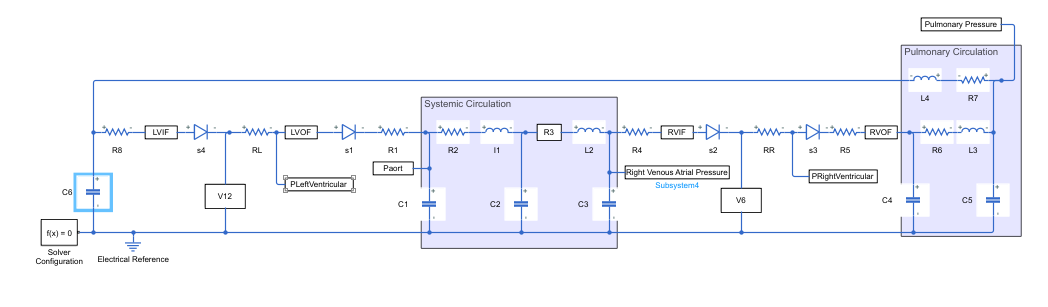

The blocks V12 and V6 represents the left and right ventricle, respectively.  According to [1], the left and right ventricle can be approximated by an isovolumetric pressure generator in series with both a time-varying elastance *E(t)* and a resistance *Rm* (denoted `RR` or `RL` in model).

Applying Kirchhoff's Law to the schematics above, you can calculate the ventricle pressure as:

where $E_d$ is a constant elastance during diastole and $E(t)$ is a variable elastance during systole.  Note that the term $R_m \frac{dV}{dt}$ active during systole is calculated outside block V12, *i.e.* it is automatically calculated by components *RL*, and *S1*.  See [2] for detailed description.  The functionality in Figure 2 above has been implemented in block V12 as follows:

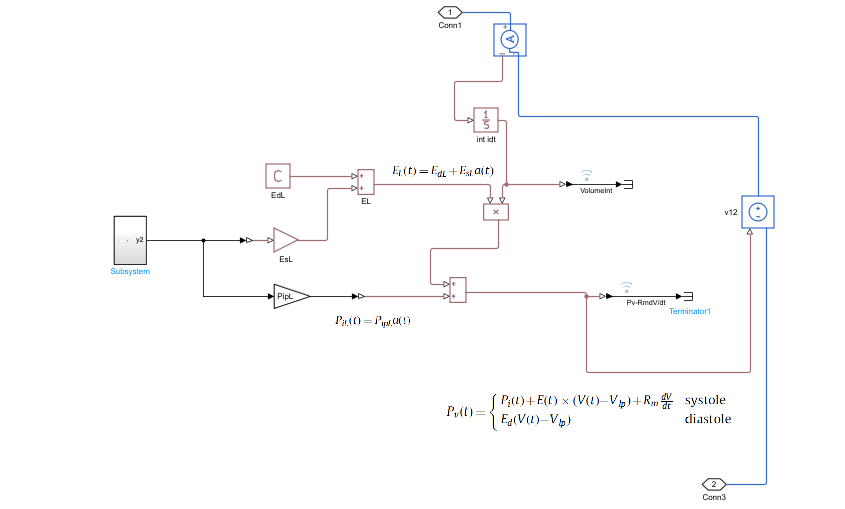

## Simulation - Normal Parameter Settings

Using the variables and initial states of the paper we achieve a good correlation between the results in the paper and model simulation. 

open("CardioVascularSystem.slx")

% Set R3 to be fixed during simulation
R3_fix = true;

% Run the simulation for 2 heartbeats
Tend = 1.6;
out = sim("CardioVascularSystem");

% Plot results for normal settings which can be compared with plots from the paper[2]
PlotCardVasSys(out)

## Simulation - Increased Systemic Resistance

Also, you can use the model to simulate different patient scenarios, such as increased systemic resistance.  In the example below, the value of R3 is increased by 100% (from 1 to 2 mmHg*s/cm^3) at time t = 1.4 seconds.

% Set variable R3 simulation
R3_fix = false;

% Run the simulation
Tend = 12;
out = sim("CardioVascularSystem");

% Plot results for normal settings which can be compared with plots from the paper[2]
PlotCardVasSys(out)

## Simulation - ECMO System

We can use this patient model for several purposes.  One example is an extracorporeal membrane oxygenation (ECMO) system, which is used to oxygenate the blood outside the patient.

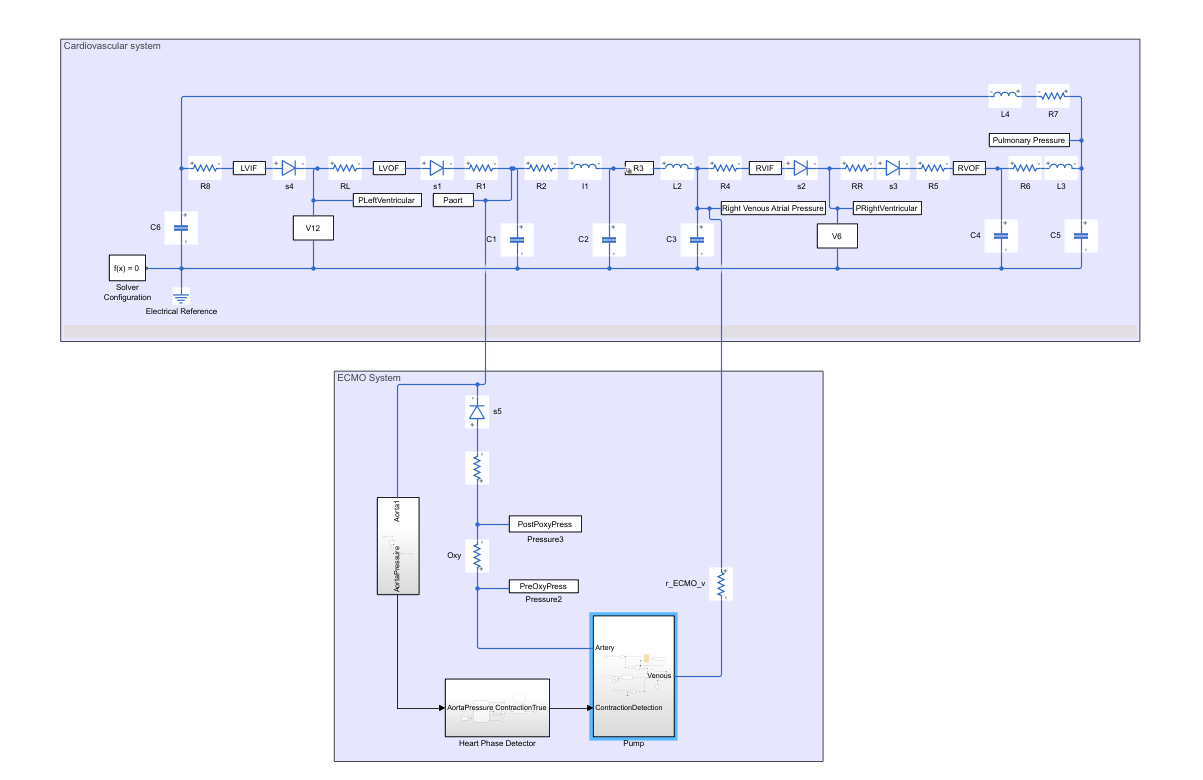

The novel ECMO system contains:

- Pressure Sensor

- Heart Phase Detector

- Plant Model of Pump

- Pump Controller

The pump controller has a fixed RPM reference value depending on the phase of the heart (0 RPM during diastole).

The heart phase detection has been implemented in Stateflow®, as follows:

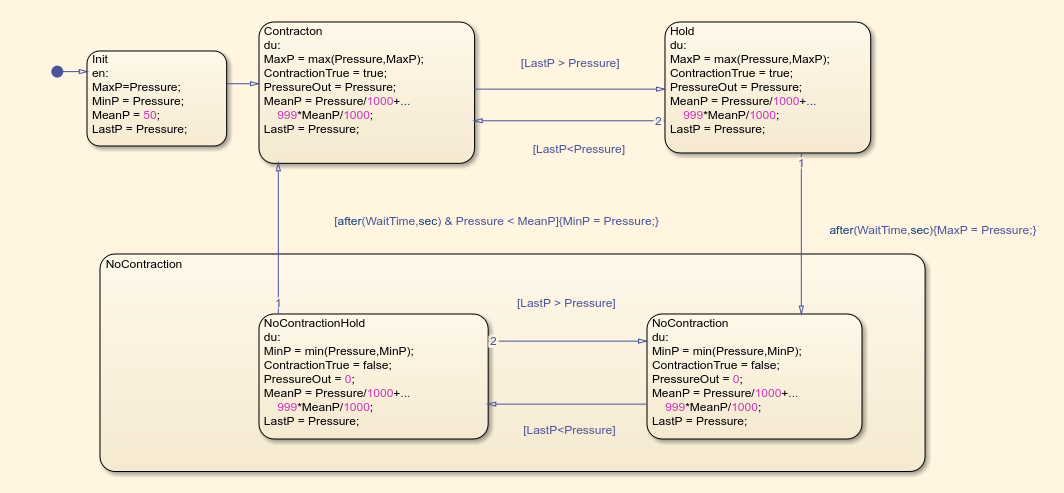

The algorithm is continuously calculating mean, max, and min values of the pressure signal.  Then, using these values and a wait time (`WaitTime`), the algorithm waits for a monotonic increase (or decrease) lasting longer than `WaitTime` until a phase change is detected.  (This is just an example and there are numerous ways to adaptively find the peak values.)

open("CardioVascularSystemWithEcmo.slx")

Running the simulation, we can analyze the ECMO system behavior for different patient situations.

% Set variable R3 simulation
R3_fix = true;

% Run the simulation
Tend = 8;
out = sim("CardioVascularSystemWithEcmo");

% Plot result
PlotECMO(out)
xlim([3.2 3.6])

As you can see in the simulation result above (and circled in Events 1 and 2 below), there is a contraction detection delay of the amount defined in `WaitTime`.  However, the deflection at Event 3 below is not mistakenly detected as a new heartbeat, which is the purpose of the design.

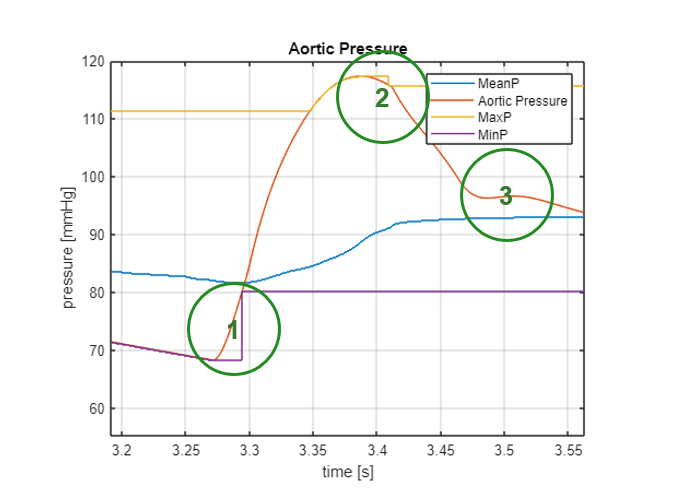

Furthermore, the pump is synchronized with the heartbeat and depending on the heart rate a second Stateflow chart is activating the pump at

- Each heartbeat,                                heartbeat <= 140

- Every other heartbeat,                     140 < heartbeat <= 150

- Every third heartbeat,                      150 < heartbeat 

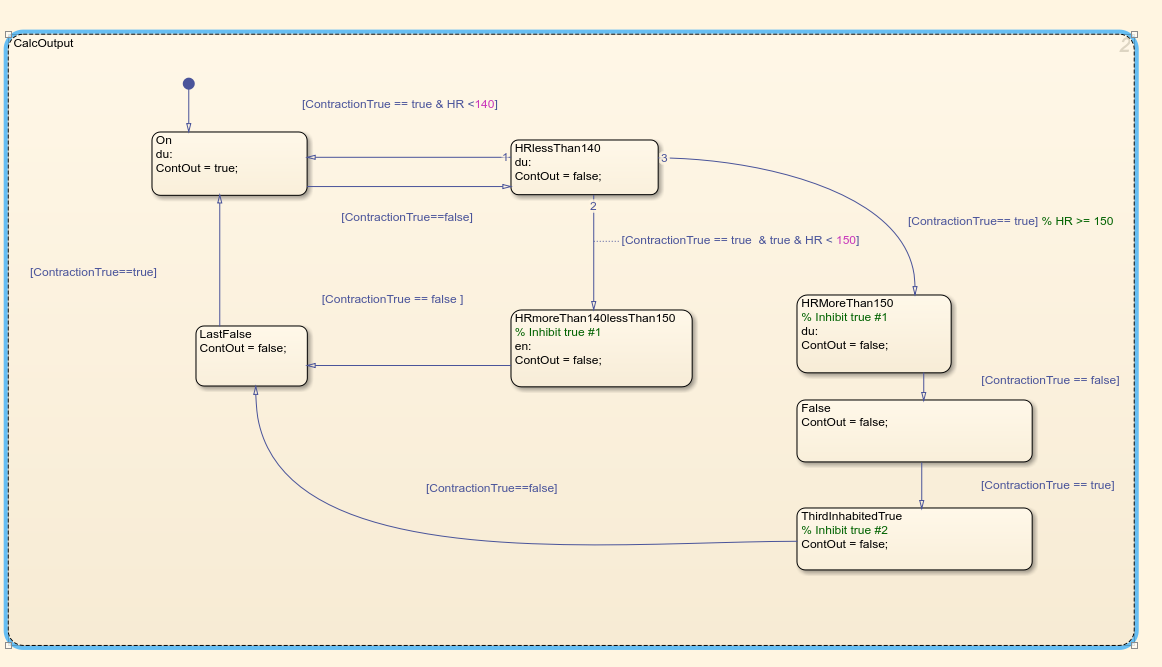

In the figure below, "`ContractionTrue`" is the output from the first Stateflow chart (as seen in the previous figure) and "`FiltContractionTrue`" is the output after it passes through the second Stateflow chart ("`ContOut`").

vars = ["ContractionTrue" "FiltContractionTrue"];
n = numel(vars);

figure
tiledlayout(n,1)
for k = 1:n
    nexttile; plot(out.logsout.getElement(vars(k)).Values)
    title(vars(k)); grid on; ylim([-0.1 1.1])
    xlabel('time [s]'); ylabel('boolean')
end

Using this simulation we can evaluate the impact of the ECMO pump on the aortic pressure.  For example, in the figure below we see that running with RPM = 3000 (blue below) versus RPM = 0 (red below) yields a small variation in aortic pressure when ECMO is activated at 3.4 and 5.8 seconds.

RPM_Range = [0 1000 2000 3000];

for ii=1:length(RPM_Range)
    in(ii) = Simulink.SimulationInput('CardioVascularSystemWithEcmo');
    in(ii) = in(ii).setVariable('RPM_Setting',RPM_Range(ii));
    in(ii) = in(ii).setVariable('Tend',8);
end

out = sim(in,"UseFastRestart","On");
PlotECMOPumpRPM(out);

## References

[1] Avanzolini, G. *et al.* (1988) “CADCS simulation of the closed-loop cardiovascular system,” *International Journal of Bio-Medical Computing*, 22(1), pp. 39–49. Available at: https://doi.org/10.1016/0020-7101(88)90006-2. 

[2] de Canete, J.F. *et al.* (2013) “Object-oriented modeling and simulation of the closed loop cardiovascular system by using SIMSCAPE,” *Computers in Biology and Medicine*, 43(4), pp. 323–333. Available at: https://doi.org/10.1016/j.compbiomed.2013.01.007. 

## Helper Plotting Functions

function PlotECMOPumpRPM(simOut)

    figure;
    tsRPM0  = simOut(1).logsout.get('Aortic Pressure');
    tsRPM3k = simOut(4).logsout.get('Aortic Pressure');
    
    plot(tsRPM0.Values.Time, tsRPM0.Values.Data, tsRPM3k.Values.Time, tsRPM3k.Values.Data)
    legend({'0 RPM','3000 RPM'},"Location","southeast")
    grid on;
    title('Impact of RPM setting for ECMO pump on Aortic Pressure')
    xlabel('Time [s]')
    ylabel('Blood pressure [mmHg]')

end

function PlotCardVasSys(out)
    tsAP    = out.logsout.get('Aortic Pressure');
    tsRVAP  = out.logsout.get('Right Venous Atrial Pressure');
    
    figure;
    subplot(2,1,1)
    plot(tsAP.Values.Time, tsAP.Values.Data);
    grid on;
    title('Aortic Pressure')
    xlabel('Time [s]')
    ylabel('Blood pressure [mmHg]')
    
    subplot(2,1,2)
    plot(tsRVAP.Values.Time, tsRVAP.Values.Data);
    grid on;
    title('Right Venous Atrial Pressure')
    xlabel('Time [s]')
    ylabel('Blood pressure [mmHg]')
end

function PlotECMO(out)
    figure
    tiledlayout(3,1)
    ax1 = nexttile([2 1]);
    hold on; grid on
    
    vars = ["MeanP" "Aortic Pressure" "MaxP" "MinP"];
    for k = 1:numel(vars)
        plot(out.logsout.getElement(vars(k)).Values)
    end
    legend(vars); title(vars(2))
    xlabel("time [s]"); ylabel("pressure [mmHg]")
    
    ax2 = nexttile;
    plot(out.logsout.getElement("ContractionTrue").Values);
    title(""); xlabel("time [s]"); ylabel("Contraction")
    ylim([-0.1 1.1]); grid on
    
    linkaxes([ax1 ax2],"x");
end
